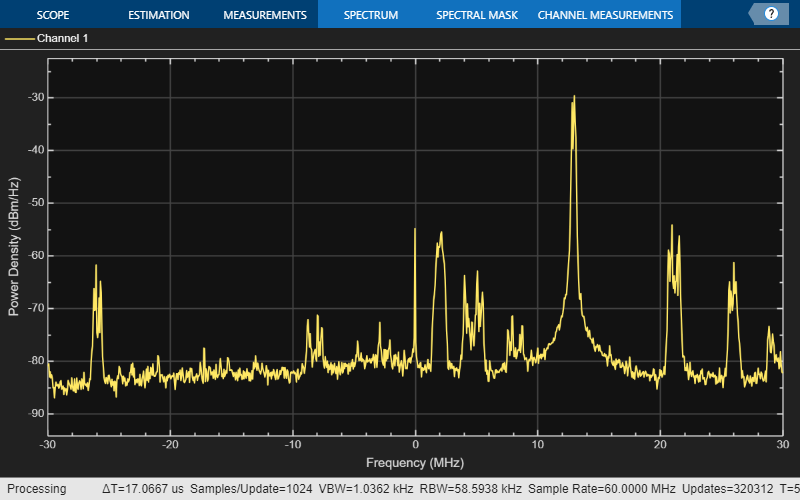

## Establishing connection to hardware. This process can take several seconds.


rx = sdrrx('Pluto');

rx.CenterFrequency = 2.4e9;
rx.BasebandSampleRate = 60e6;
rx.SamplesPerFrame = 20000;
rx.OutputDataType = 'double';

sa = spectrumAnalyzer( ...
'SampleRate', rx.BasebandSampleRate, ...
'SpectrumType', 'Power density', ...
'ShowLegend', true);

while true
    data = rx();
    sa(data);
end


% Question 1: -68 dB/dBm

% Question 2: 2.34, 2.4, 2.42, 2.46 Observed peaks at 20 MHz baseband
% sample rate

% Question 3: Didn't see any observable changes with a 60 MHz baseband sample rate at
% 2.44 GHz center frequency

% Question 4: No

% Question 5: No